Vamos a resolver la siguiente ecuación


$$\frac{d^2y}{dt^2} + a \frac{dy}{dt} + 9 y =100$$


Donde el parametro a será una constante la cual iremos variando, para esto haremos uso de los ciclos y resolveremos este ejercicio mediante ciclos for y ciclos while.

Con las siguientes condiciones iniciales


$$y(0)=0, \;\;\; y\prime(0)=0$$


La primera forma en que lo resolveremos será con el ciclo "while"

Definimos nuestro parametro de evolución, el rango de valores de t y las condiciones iniciales.

tic,i=1;
rvt=linspace(0,4,2^6);
ci=[0;0];
a=[2,6,10];

a =      2     6    10


Ahora iniciamos el ciclo, en cada iteración creara una nueva funcion f con el parametro i diferente, que sera i=2,6,10. Tambien mandamos a resolver la ecuacion y a graficiar. Posteriormente seguimos aumentando los parametros.

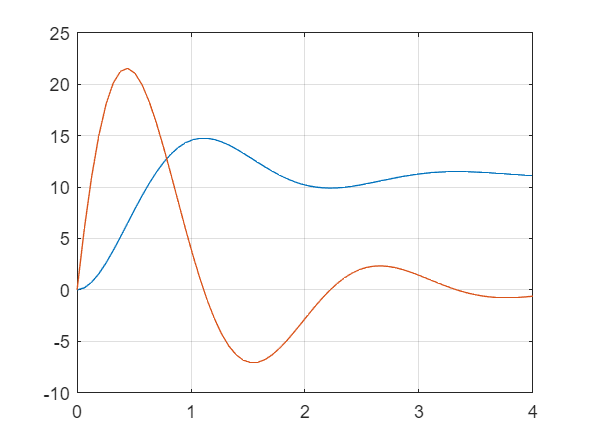

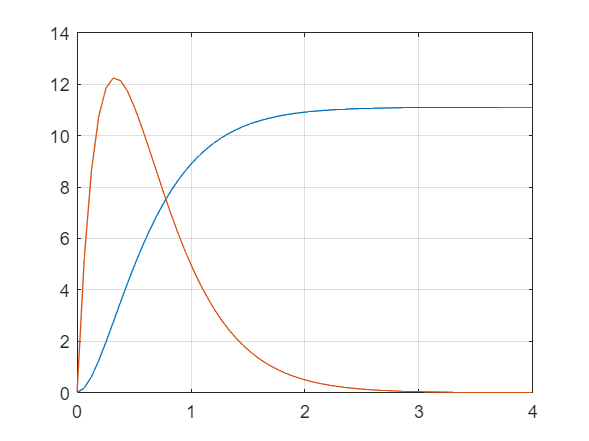

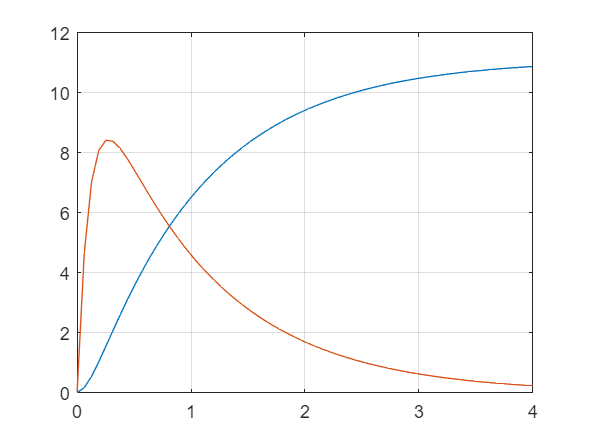

Elapsed time is 0.360275 seconds.


while i<4
    f=@(t,y) [y(2);-a(i)*y(2)-9*y(1)+100];
    [t,y]=ode45(f,rvt,ci);
    figure, plot(t,y), hold off, grid
    i=i+1;
end, toc

Ahora lo resolveremos a traves del comando "for", primero introducimos los parametros en el vector a, el rango de valores de t y las condiciones inicales.

tic,a=[2,6,10];
rvt=linspace(0,4,2^6);
ci=[0;0];

Iniciamos el comando "for", en cada iteración me creara una funcion f con un valor diferente de i. 

f = function_handle with value:
    @(t,y)[y(2);-i*y(2)-9*y(1)+100]


f = function_handle with value:
    @(t,y)[y(2);-i*y(2)-9*y(1)+100]


f = function_handle with value:
    @(t,y)[y(2);-i*y(2)-9*y(1)+100]


Elapsed time is 0.747892 seconds.


for i = a
    f=@(t,y) [y(2);-i*y(2)-9*y(1)+100]
    [t,y]=ode45(f,rvt,ci);
    figure, plot(t,y), grid
end, toc